# 测试

clc
clear
close all
addpath("src\");

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [8000., -2200., 100., 0., 0., 0.]';  % m, m/s
% n = 0.00115691; 
% tf = 8 * 3600;
% x0 = [-20e3 20e3 20e3 0.0467472e3 0.00930458e3 0.00798343e3]';
step = 1.;
% [t, x] = CwRendezvousLowThrust(x0, n, tf, step);
[t, x, lambda0] = CwDirOpt(x0, n, tf, step);

Optimization terminated: maximum number of generations exceeded.


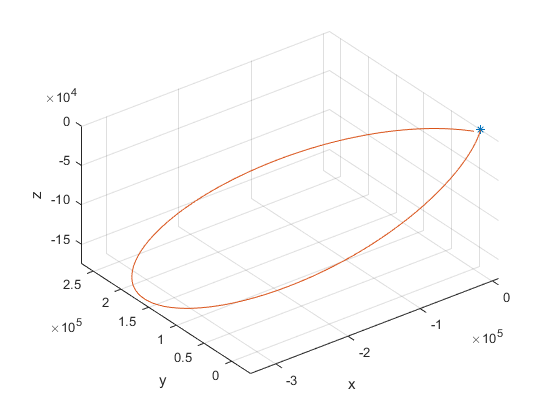

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

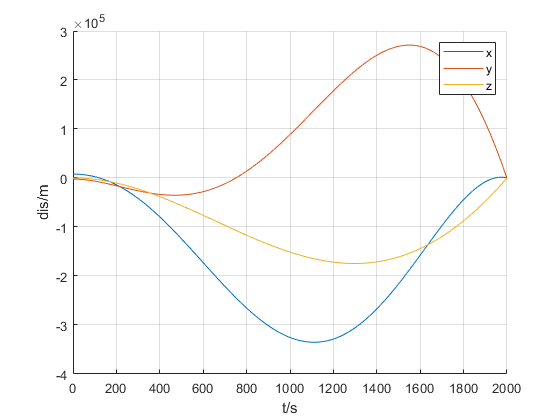

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off